
rng(0,'twister');
N = 100;
x = linspace(-10,10,N)';
y = sin(x) + 0.01*randn(N,1);

F=ksdensity(y, x)

F =    1.0e-69 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.8485


F_u = ksdensity(x,x)

F_u =     0.0254
    0.0266
    0.0279
    0.0291
    0.0304
    0.0316
    0.0327
    0.0339
    0.0350
    0.0361


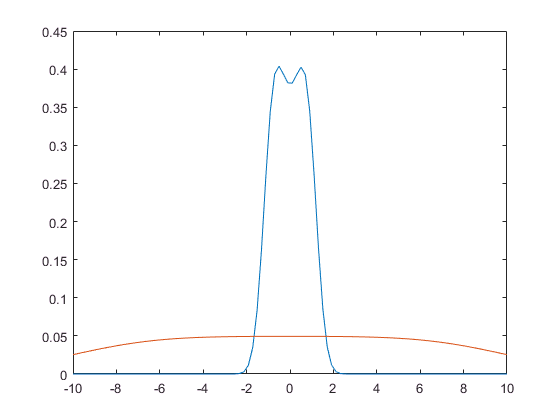


plot(x, F)
hold on
plot(x,F_u)

T = F ./F_u

T =    1.0e-67 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2353




% % 2. Fit the model using 'exact' and predict using 'exact'.
% gpr = fitrgp(x,y,'Basis','linear','Optimizer','QuasiNewton',...
%     'verbose',1,'FitMethod','exact','PredictMethod','exact');
% 
% % 3. Plot results.
% plot(x,y,'r');
% hold on;
% plot(x,resubPredict(gpr),'b');
% xlabel('x');
% ylabel('y');
% legend('Data','GPR fit');